% % Define the eddy
% A = 0.10; % amplitude in m
% L = 80e3; % length in m
% eddy = @(r) A*exp(-r.*r/L/L);
% 
% % Create some noise
sigma = 10;%0.01;
noiseDistribution = StudentTDistribution(sigma,3.0);
% noiseDistribution = NormalDistribution(sigma);
% 
% % Now create some observations of the eddy with noise
% % rng(1)
% r = linspace(0,4*L,100).';
% ssh = eddy(r) + noiseDistribution.rand(size(r));
%%
for i=1:length(timet)
        match_idx=find(date_eddy==datenum(dateshift(time(i), 'start', 'day')));
        % xEt(i)=xt(i)-xo(match_idx);
        % yEt(i)=yt(i)-yo(match_idx);
        r2D(i)=sqrt(xt(i)-xo(match_idx).^2+yt(i)-yo(match_idx).^2);
end
r=r2D(~isnan(r2D));
% xEt, yEt, ssht are arrays
% r2D=sqrt(xEt.^2+yEt.^2);r=r2D(~isnan(r2D));
ssht1D=ssht(~isnan(r2D));
%mapped
% r=sqrt(xMat(:).^2+yMat(:).^2);
% ssht=aviso_sla(:);
L=max(r);

% create a spline basis
% M indicates how many splines to create
K = 4; % *order* of the spline (K=4 is a cubic spline)
tKnot = BSpline.knotPointsForDataPoints(sort(r),K=K,M=4);

% Do a simple least-squares fit to the data with these splines
constraints = struct('t',[],'D',[]);
spline = ConstrainedSpline(r,ssht1D,K,tKnot,noiseDistribution,constraints);

Error using BSpline.Spline
t_knot must be non-decreasing.

Error in ConstrainedSpline.PrecomputeSolutionMatrices (line 135)
                cachedVars.X = BSpline.Spline( t, t_knot, K, 0 ); % NxM

Error in ConstrainedSpline.ConstrainedSolution (

% spline = ConstrainedSpline(r,ssht,K,tKnot,constraints);
tq = linspace(0,4*L,1000).';

figure
tl = tiledlayout(1,2,TileSpacing="tight");
nexttile

% plot(tq/1e3,eddy(tq),Color=[0 0 0],LineWidth=1.0)
scatter(r,ssht1D,1,'k', 'filled'), hold on
plot(tq,spline(tq),Color='r',LineWidth=2)
xlabel('radial distance (km)')
ylabel('SSH (cm)')
title('Unconstrained fit')
xlim([0 max(r)])
% ylim([-3*sigma eddy(0)+3*sigma])


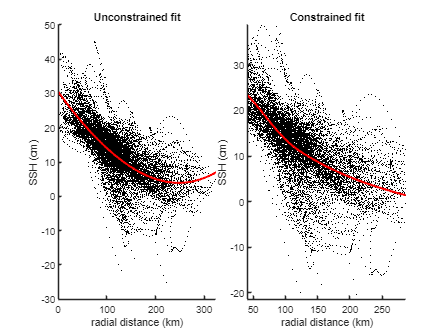

% The constraints let you set the value of the spline, or a derivative, to
% zero. So this example forces the fit to be zero at r_max, and the first
% derivative to be zero at r=0. We add two more splines, because we are
% adding two constraints.
tKnot = BSpline.knotPointsForDataPoints(sort(r),K=K,M=6);
% constraints = struct('t',[min(r); max(r); max(r)],'D',[1;0;1]);%max(r)
constraints = struct(...
    't', [min(r); max(r); max(r)], ...  % points to apply contraints
    'D', [1; 0; 2] ...                  % derivatives
    );

spline_constrained = ConstrainedSpline(r,ssht1D,K,tKnot,noiseDistribution,constraints);

nexttile
% plot(tq/1e3,eddy(tq),Color=[0 0 0],LineWidth=1.0), hold on
scatter(r,ssht1D,1,'k', 'filled'), hold on
plot(tq,spline_constrained(tq),Color='r',LineWidth=2)
% set(gca,'YTickLabel',[]);
xlabel('radial distance (km)')
ylabel('SSH (cm)')
title('Constrained fit')
xlim([0 max(r)])

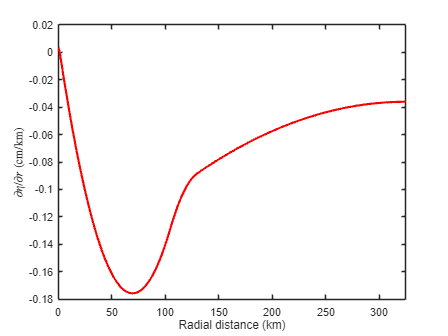

% ylim([-3*sigma eddy(0)+3*sigma])

% Xn = BSpline.Spline( t_spline, tKnot, K, 0 );
% xi = Xn\x_spline;%how should I allow nan
% B = BSpline.Spline( tq, tKnot, K, 1 );
Vq = squeeze(spline_constrained(tq).B(:,:,2));
figure, 
% plot(tq,Vq)%Vq*xi)
plot(tq,gradient(spline_constrained(tq))./gradient(tq),Color='r',LineWidth=2)
xlim([0 max(r)])
xlabel('Radial distance (km)'),ylabel('$\partial\eta/\partial r$ (cm/km)','interpreter','latex')


figure;plot(rmid_mapped,gradient(mz_mapped)./gradient(rmid_mapped),Color='k',LineWidth=3)

Unrecognized function or variable 'rmid_mapped'.

hold on;plot(rmid_at,gradient(mz_at)./gradient(rmid_at),Color=[],LineWidth=3)
set(gca, 'fontname', 'times','fontsize',16)
xlabel('Radial distance (km)'),ylabel('$\partial\eta/\partial r$ (cm/km)','interpreter','latex')
xlim([0 250])
box off